Note: include a plot of the stress statistics, showing the mean stress +/- 6 standard deviations as a function of distance along the spar, for both the nominal (for verification) and the optimal spar.

## Initialize

clear all;
% close all;
set(0,'DefaultFigureWindowStyle','docked')

## Variables

Length (wing semi-span)

L = 7.5;%m

Total mass

m = 500;%kg

### Material Properties (Carbon fiber composite)

Density

rho = 1600;%kg/m^3

Young’s modulus 

E = 70e9;%Pa

Ultimate tensile/compressive strength

Su = 600e6;%Pa

### Constrains

Inner Radius Minimum

r_min = 1e-2;%m

Outer Radius Maximum

R_max = 5e-2;%m

Minimum Thickness

t_min = 2.5e-3;%m

### Design Variables

Nelem_array = 4:2:200;
DV = @(Nelem) DesVars(Nelem,L);
stress = @(r, force, Nelem) sigma(r, force, Nelem, L, E);


$$r=\left\lbrack \begin{array}{c}
r_1 \\
r_2 \\
\vdots \\
R_1 \\
R_2 \\
\vdots 
\end{array}\right\rbrack$$


## Mesh Convergence Study

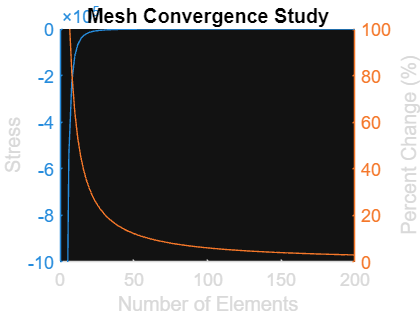

s_tip = zeros(size(Nelem_array));
m_array = zeros(size(Nelem_array));
pdiff = zeros(size(Nelem_array));
pdiff(1) = NaN;
for i=1:size(Nelem_array,2)
    Nelem=Nelem_array(i);
    [r,x] = DV(Nelem);
    m_array(i) = Objective(L, r, rho, Nelem); 

    Iyy = MoI(r);
    [u] = CalcBeamDisplacement(L, E, Iyy, fnom(x), Nelem);
    [~,zmax] = ExtractRadii(r);
    [s] = CalcBeamStress(L, E, zmax, u, Nelem);
    s_tip(i) = s(end); 
    if i>1
        pdiff(i)=abs(200*(s(end)-s_tip(i-1))/(s(end)+s_tip(i-1)));
    end
end

mesh = figure();
hold on
title('Mesh Convergence Study',"Color","k")
xlabel("Number of Elements")

yyaxis left
semilogy(Nelem_array,s_tip)
% set(gca, 'YDir','reverse')
ylabel("Stress")
ylim([-1e6 0])

yyaxis right
plot(Nelem_array,pdiff)
ylabel("Percent Change (%)")
ylim([0 100])
hold off


Nelem = Nelem_array(find(pdiff < 5,1))

Nelem =    122


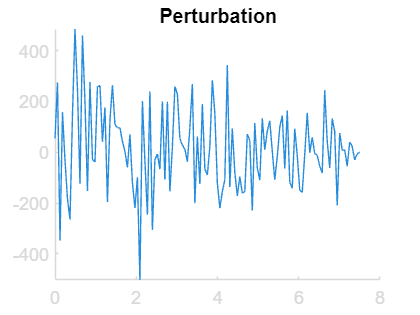

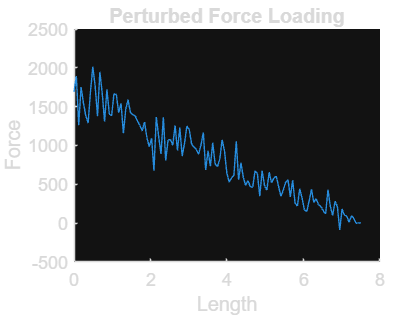

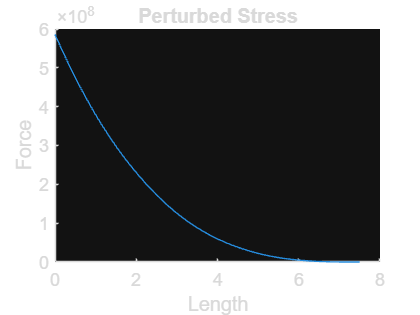

[r,x,Nnode,Nvar] = DV(Nelem);

## Optimization

Inequality Matrix

Aineq = zeros([Nnode Nvar]);


$$A=\left\lbrack \begin{array}{ccccccccc}
1 & 0 & \cdots  & 0 &  & -1 & 0 & \cdots  & 0\\
0 & 1 & \cdots  & 0 &  & 0 & -1 & \cdots  & 0\\
\vdots  & \vdots  & \ddots  & \vdots  &  & \vdots  & \vdots  & \ddots  & \vdots \\
0 & 0 & 0 & 1 &  & 0 & 0 & 0 & -1
\end{array}\right\rbrack$$


A = zeros(Nnode,Nvar);
for k = 1:(Nnode)
    A(k,k) = 1.0;
    A(k,Nelem+1+k) = -1.0;
end
b = -0.0025*ones(Nnode,1);

Upper and Lower bounds

fix this

lb = r_min*ones(Nvar,1);
ub = R_max*ones(Nvar,1);

fun = @(r) SparWeight(r, L, rho, Nelem);
nonlcon = @(r) WingConstraints(r, L, E, force, Su, Nelem);
options = optimset('GradObj','on','GradConstr','on', 'TolCon', 1e-4, 'TolX', 1e-8, 'Display','iter', 'Algorithm', 'active-set','OutputFcn',@outfun);
[r_opt,fval] = fmincon(fun, r, A, b, [], [], lb, ub, nonlcon, options);

## Optimized

Plot Feasibility

fplot = figure();
hold on
title('Optimization')
xlabel('Iteration') 
lastiter = find(feashistory == 0,1,'last');
feas = feashistory(lastiter:end);
optim = optimhistory(lastiter:end);
iter = 1:size(feas);
semilogy(iter,feas)
semilogy(iter,[NaN;optim])
legend('Feasibility','First Order Optimality')
hold off

Cross Section

csplot = figure();
hold on
[r_in, r_out] = ExtractRadii(r_opt);
plot(x,r_in,'b-')
plot(x,r_out,'b-')
% legend('Original','','Optimized','')
hold off

Optimized Displacement

uplot = figure();
hold on
Iyy = MoI(r_opt);
[u] = CalcBeamDisplacement(L, E, Iyy, fnom(x), Nelem);
plot(x,u(1:2:2*(Nelem+1)),'b');
% legend("Original","Optimized")
hold off

Optimized Stresses

splot = figure();
hold on
[s] = CalcBeamStress(L, E, r_out, u, Nelem);
plot(x,s,'b')
% legend("Original","Optimized")
hold off

## Geometry

geo = figure(6);
[X,Y,Z] = cylinder(r_out);
surf(X,Z*L,Y)
ylim([0 L])
xlim([-.5 .5])
zlim([-.5 .5])
view([-260 30])
zlabel('Radius (m)')
xlabel('Radius (m)')
title('3D Model of Spar')

allfigs = findall(groot, 'type', 'figure');
allaxis = findall(0, 'type', 'axis');
titles = findall(groot, 'type', 'title');
set(allaxis, 'Color', 'k', {'XColor', 'YColor'}, {'k','k'});
% set([f2, f3], 'Color', 'k')

hAxes = findobj(0,"Type","axes");
for i=1:size(hAxes,1)
    hAxes(i).Color = [1,1,1];
    hAxes(i).XColor = [0,0,0];
    hAxes(i).YColor = [0,0,0];
    hAxes(i).ZColor = [0,0,0];
end

## Save

saveas(uplot, 'Plots/Displacement.png');
saveas(splot, 'Plots/Stress.png');
% saveas(mesh, 'Plots/Mesh.png');
saveas(fplot, 'Plots/Feasibility.png');
saveas(csplot, 'Plots/Cross Section.png');
saveas(geo, 'Plots/Geometry.png');
% saveas(force_plot, 'Plots/Force.png');
save opt.mat

## Functions

Design Variables

function [r,x,Nnode,Nvar] = DesVars(Nelem,L)
% Returns the Design Variables
    Nnode = Nelem+1;
    Nvar = 2*(Nnode);
    r = zeros(2*(Nelem+1),1);
    r(1:Nelem+1) = 0.04625*ones(Nelem+1,1);
    r(Nelem+2:2*(Nelem+1)) = 0.05*ones(Nelem+1,1);
    x = 0:L/Nelem:L;
end

Nominal Force

function F = fnom(x)
    %Total Mass
    m = 500;%kg
    L = 7.5;%m
    g = 9.81;%m/s^2
    W = g*m;
    F = 2.5*W/L*(1-x'/L);
end

Stress

function s = sigma(r, force, Nelem, L, E)
    [r_in, r_out] = ExtractRadii(r);
    Iyy = CalcSecondMomentAnnulus(r_in, r_out);
    u = CalcBeamDisplacement(L, E, Iyy, force, Nelem);
    s = CalcBeamStress(L, E, r_out, u, Nelem);
end